### Question 01

tspan = [0 4];
I0 = 0;
G0 = 0;

#### step input to a normal person

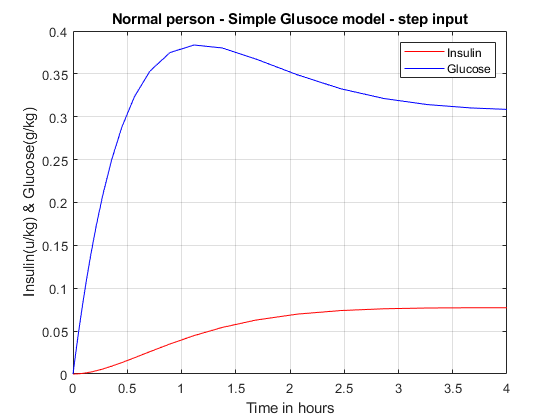

[t,y] = ode23(@(t,y) [-0.8 0.2;-5 -2]*y+transpose([0 1]), tspan, [I0 G0]);
plot(t,y(:,1),'r-',t,y(:,2),'b-');
xlabel('Time in hours');
ylabel('Insulin(u/kg) & Glucose(g/kg)');
title('Normal person - Simple Glusoce model - step input');
legend('Insulin', 'Glucose');
grid on;

#### Bolus input to a normal person

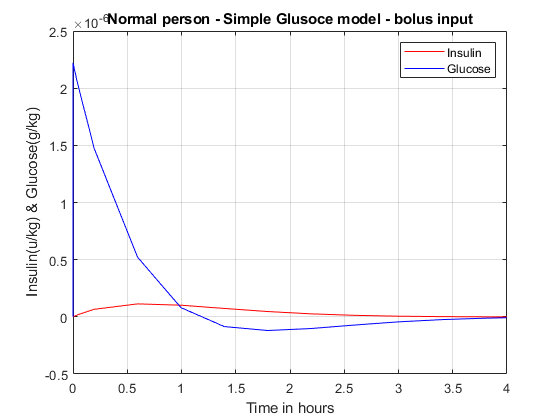

[t,y] = ode23(@(t,y) [-0.8 0.2;-5 -2]*y+transpose([0 1-sign(t)]), tspan, [I0 G0]);
plot(t,y(:,1),'r-',t,y(:,2),'b-');
xlabel('Time in hours');
ylabel('Insulin(u/kg) & Glucose(g/kg)');
title('Normal person - Simple Glusoce model - bolus input');
legend('Insulin', 'Glucose');
grid on;

#### Step input to a diabetic patient

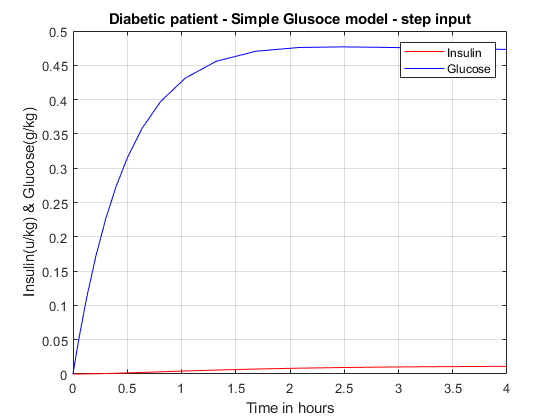

[t,y] = ode23(@(t,y) [-0.8 0.02;-5 -2]*y+ transpose([0 1]), tspan, [I0 G0]);
plot(t,y(:,1),'r-',t,y(:,2),'b-');
xlabel('Time in hours');
ylabel('Insulin(u/kg) & Glucose(g/kg)');
title('Diabetic patient - Simple Glusoce model - step input');
legend('Insulin', 'Glucose');
grid on;

#### Step input to a diabetic patient with glucose infussion 

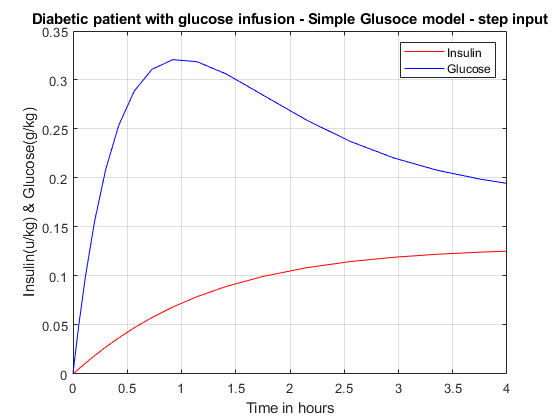

[t,y] = ode23(@(t,y) [-0.8 0.02;-5 -2]*y+transpose([0.1 1]), tspan, [I0 G0]);
plot(t,y(:,1),'r-',t,y(:,2),'b-');
xlabel('Time in hours');
ylabel('Insulin(u/kg) & Glucose(g/kg)');
title('Diabetic patient with glucose infusion - Simple Glusoce model - step input');
legend('Insulin', 'Glucose');
grid on;

### Question 02

#### Iodine intake normal - 10 days

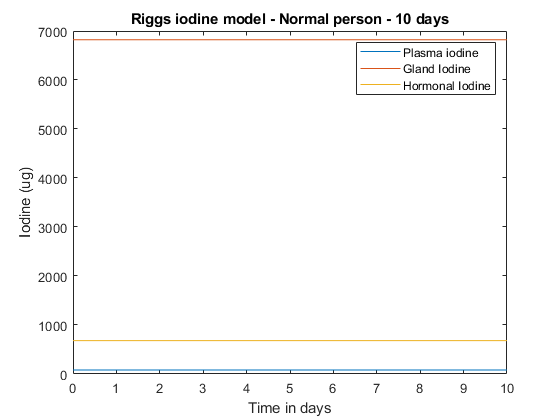

I0 = 81.2;
G0 = 6821;
H0 = 682.1;

tspan = [0 10];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Normal person - 10 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine");

#### Iodine intake normal - 300 days

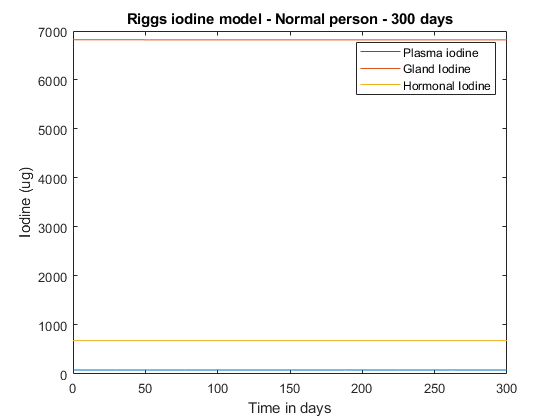

tspan = [0 300];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Normal person - 300 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine");

#### Drop in intake - 10 days

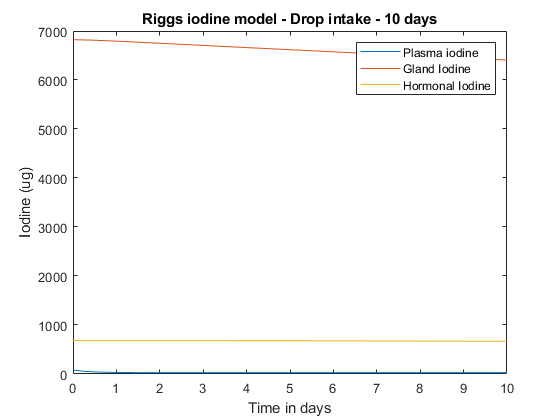

tspan = [0 10];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([15 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Drop intake - 10 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

#### Drop in intake - 300 days

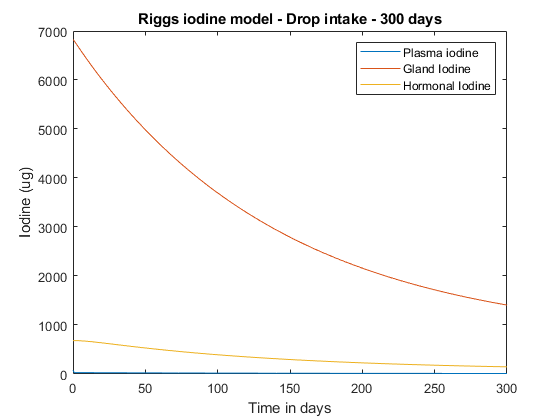

tspan = [0 300];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([15 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Drop intake - 300 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

#### Hypothyroidism due to autoimmune thyroid disease

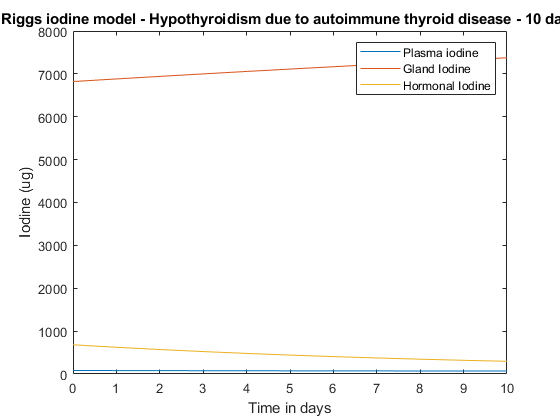

tspan = [0 10];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.001 0;0 0.001 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hypothyroidism due to autoimmune thyroid disease - 10 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

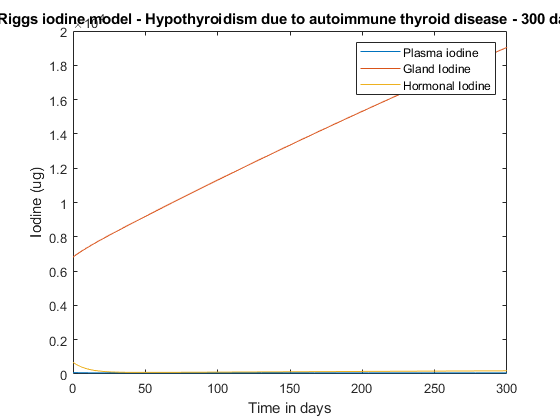


tspan = [0 300];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.001 0;0 0.001 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hypothyroidism due to autoimmune thyroid disease - 300 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

#### Hypothyroidism due to low Iodine intake

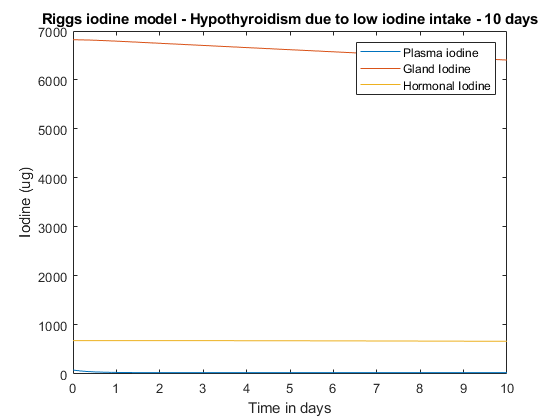

tspan = [0 10];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([15 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hypothyroidism due to low iodine intake - 10 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

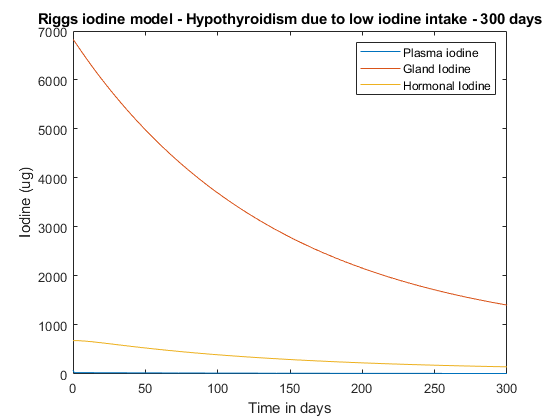

tspan = [0 300];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.01 0;0 0.01 -0.1]*y+transpose([15 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hypothyroidism due to low iodine intake - 300 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

#### Hyperthyroidism due to Grave’s disease

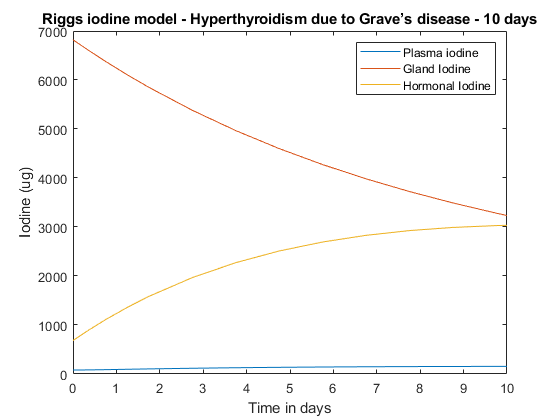

tspan = [0 10];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.1 0;0 0.1 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hyperthyroidism due to Grave’s disease - 10 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

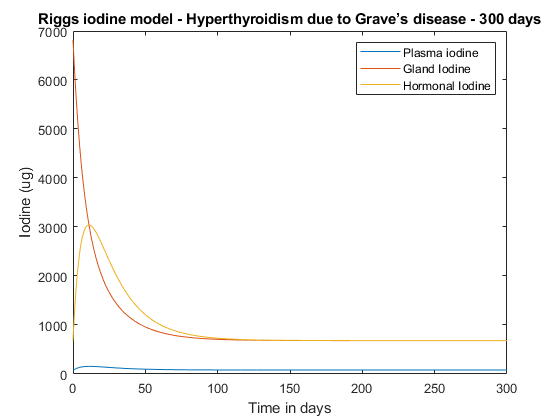

tspan = [0 300];
[t,y] = ode23(@(t,y) [-2.52 0 0.08;0.84 -0.1 0;0 0.1 -0.1]*y+transpose([150 0 0]), tspan, [I0 G0 H0]);
plot(t,y);
xlabel("Time in days"); ylabel("Iodine (ug)");
title("Riggs iodine model - Hyperthyroidism due to Grave’s disease - 300 days");
legend("Plasma iodine", "Gland Iodine", "Hormonal Iodine")

### Part 3 - Plot

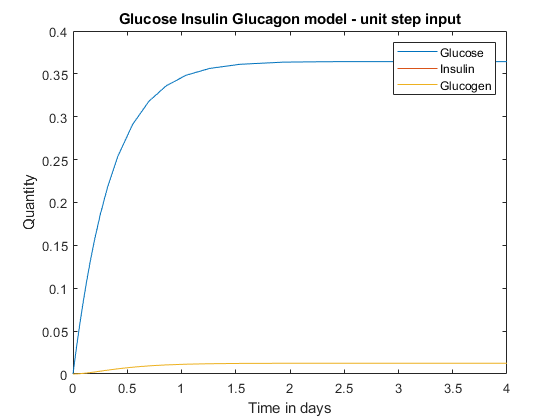

tspan = [0 4];
Glucose0 = 0;
Insulin0 = 0;
Glucagon0= 0;

[t,y] = ode23(@(t,y) [-2.4 -5 -5;0.2 -5.8 0;0.2 0 -5.8]*y+transpose([1 0 0]), tspan, [Glucose0 Insulin0 Glucagon0]);
plot(t,y);
xlabel("Time in days"); ylabel("Quantity");
title("Glucose Insulin Glucagon model - unit step input");
legend("Glucose", "Insulin", "Glucogen")